# First Order System 

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

## Introduction 

This notebook provides introduction to models for basic first order systems. 

First order systems are systems whose input-output relationship is a first order differential equation. 


$$a_1 \frac{d\;y\left(t\right)}{\textrm{dt}}+a_0 \;y\left(t\right)=b_0 \;x\left(t\right)\;$$


First order systems have single energy storing elements such as capacitor or inductor. 

For the purpose of this model, we will be considing a RC circuit with a step response. 

The value of the unit step response is zero at t = 0 and for all negative values of t. It will slowly increase from zero value and finally reaches its steady state value. 

## Model 

The following simple model was created on Simscape to monitor the voltage across the capacitor with a unit step input voltage. 

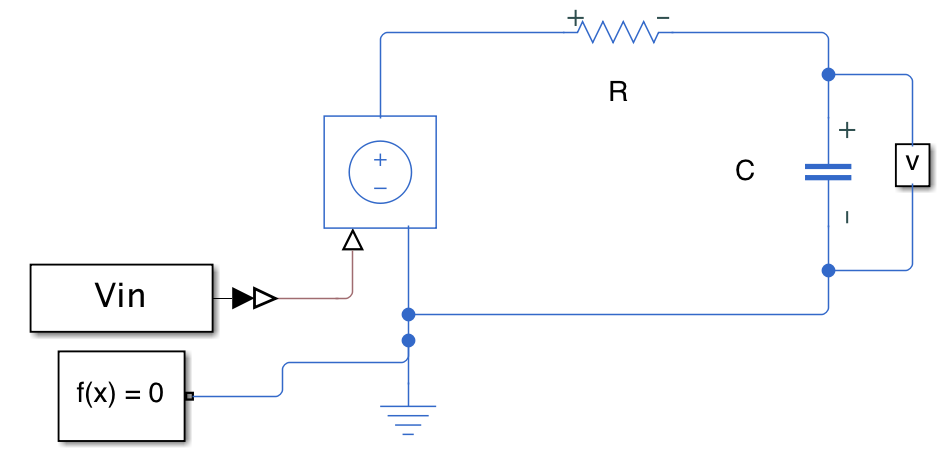

The parameters and chosen values for this circuit include: 

- Resistance: R = 100 kOhm

- Capacitance: C = 800 nF

- Series resistance: r = 1e-6 Ohm 

These values will be set into the simscape model:

model_name = 'FirstorderStep';
open_system(model_name);


set_param('FirstorderStep/R','R','100')
set_param('FirstorderStep/C','c','800')
set_param('FirstorderStep/C','r','1e-6')

T=0.0001;
fs=1/T;
t=0:T:2; %time;
Vin(:,1)=t;
Vin(:,2)=sin(2*pi*t*60);


simOut = sim('FirstorderStep', 'CaptureErrors', 'on');

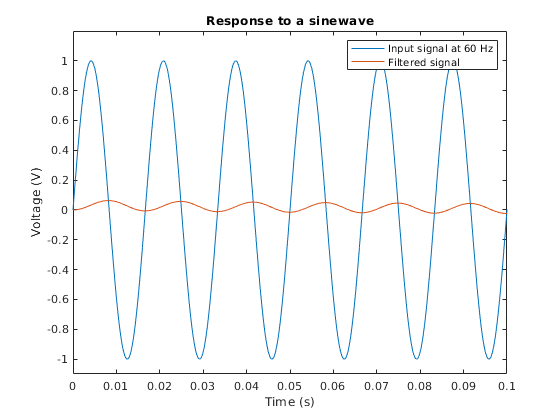

figure
plot(Vin(:,1),Vin(:,2))
hold on
plot(simOut.out.Time,simOut.out.Data(:,1))
title('Response to a sinewave')
xlabel('Time (s)')
ylabel('Voltage (V)')
legend('Input signal at 60 Hz','Filtered signal')
xlim([0, 0.1])
ylim([-1.1, 1.2])


    figure
    N=length(Vin(:,2));
    Y = fft(Vin(:,2));
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);

    P1(2:end-1) = 2*P1(2:end-1);
    f = fs*(0:(N/2))/N;
    plot(f,P1) 
    hold on
    N=length(simOut.out.Data(:,1));
    Y = fft(simOut.out.Data(:,1));
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);

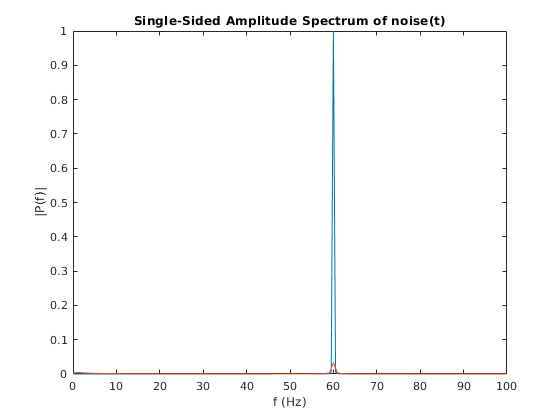

    P1(2:end-1) = 2*P1(2:end-1);
    f = fs*(0:(N/2))/N;
    plot(f,P1)    
    title('Single-Sided Amplitude Spectrum of noise(t)')
    xlabel('f (Hz)')
    ylabel('|P(f)|')
    xlim([0,100])

Bode plot

    %% Specify the model name
model = 'FirstorderStep';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
io = getlinio(model);

%% Specify the operating point
% Use the model initial condition
op = operpoint(model);



%% Linearize the model
sys = linearize(model,io,op);

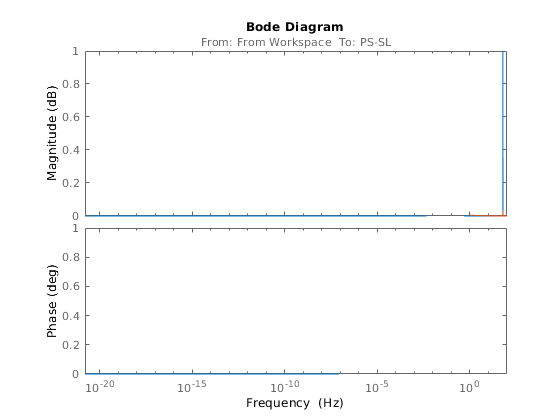


%% Plot the resulting linearization
bode(sys)

## Configure Input 

The unit step signal is configured as an input to the first order system. Tau is the time constant and in one time constant, the response curve should be at 63% of the final value. At five time constants, the response should reach 99% of the final value. The steady state can only be reached after an infinite amount of time however in practice it is reasonable to consider the time it takes to reach within 2% of the final value. 

clear all
T=0.001;
Vin(:,1)=0:T:2; %time;
Vin(1:200,2)=0;
Vin(201:end,2)=5;

%sim(model_name)
tau=100e3*800e-9;
one_tau=0.2+tau;
v_one_tau=5*0.63;
five_tau=0.2+5*tau

five_tau = 0.6000

## Plot Response 

The exponetial respose curve is plotted here, it includes the voltage as a function of time for a simulation time of 1 s. The response reaches 63% of it's final value at tau and 99% at five tau. 

simOut = sim('FirstorderStep', 'CaptureErrors', 'on');

figure
plot(Vin(:,1),Vin(:,2))
hold on
plot(simOut.out.Time,simOut.out.Data(:,1))
legend("V_{in}","V_o")
ylim([-0.1,6])
a1=line([one_tau one_tau],[0 v_one_tau],'Color','red','LineStyle','-.')

a1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-.'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.2800 0.2800]
              YData: [0 3.1500]
              ZData: [1×0 double]

  Show all properties


a2=line([0 one_tau],[v_one_tau v_one_tau],'Color','red','LineStyle','-.')

a2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-.'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.2800]
              YData: [3.1500 3.1500]
              ZData: [1×0 double]

  Show all properties


a3=line([five_tau five_tau],[0 5],'Color','red','LineStyle','-.')

a3 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-.'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.6000 0.6000]
              YData: [0 5]
              ZData: [1×0 double]

  Show all properties


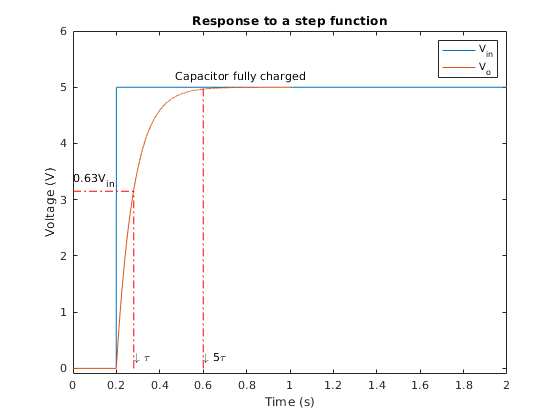

str = '\downarrow \tau';
text(one_tau,0+0.2,str)
text(0,v_one_tau+0.2,'0.63V_{in}')
text(five_tau-0.13,5+0.2,'Capacitor fully charged')
text(five_tau,0.2,'\downarrow 5\tau')

%a4=line([0 1],[5 5],'Color','magenta','LineStyle','-.')

title('Response to a step function')
xlabel('Time (s)')
ylabel('Voltage (V)')
legend("V_{in}","V_o")